# Exploring the Discrete-time Fourier Transform

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Winter 2018.

Let's look at the DTFT of a real-world, discrete-time signal in order to get our hands dirty. We'll again use the famous 'Cameraman' image.

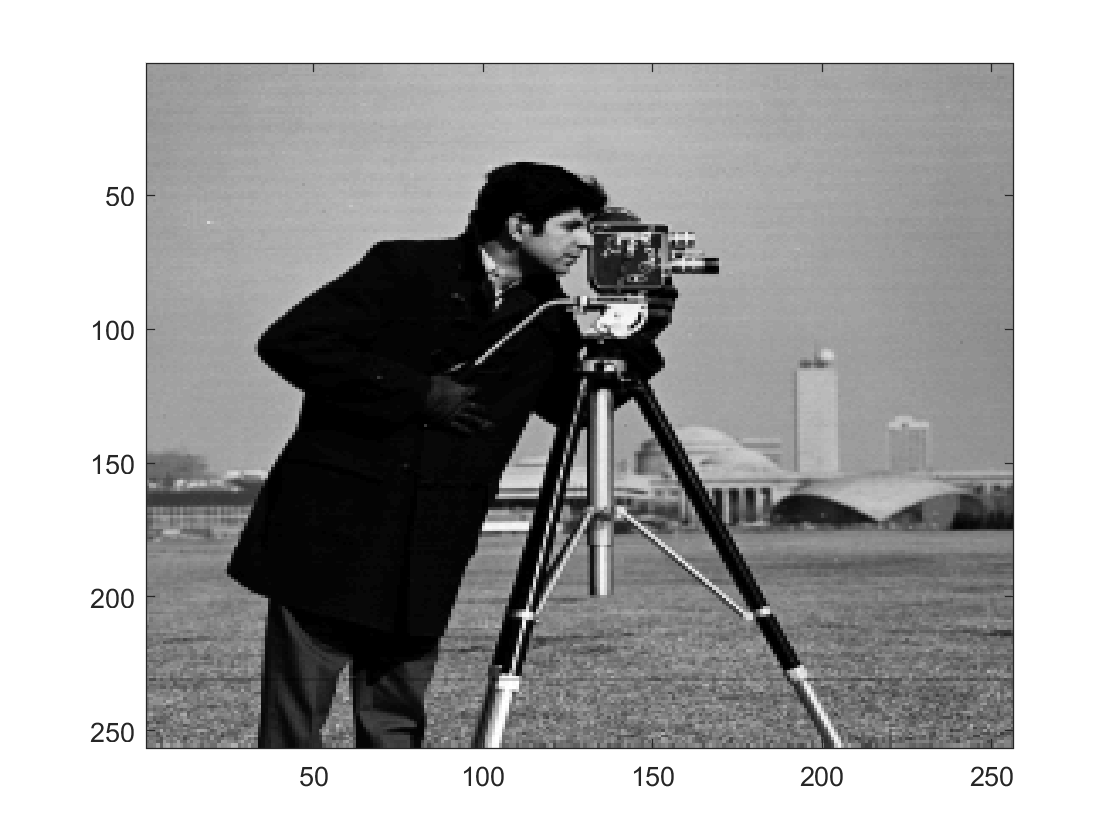

close all;
I = imread('cameraman.tif');
imagesc(I);
colormap gray;

HEIGHT = size(I,1);
LENGTH = size(I,2);

Recall that we can "vectorize" this image into a discrete-time signal. We can take and plot its DTFT.

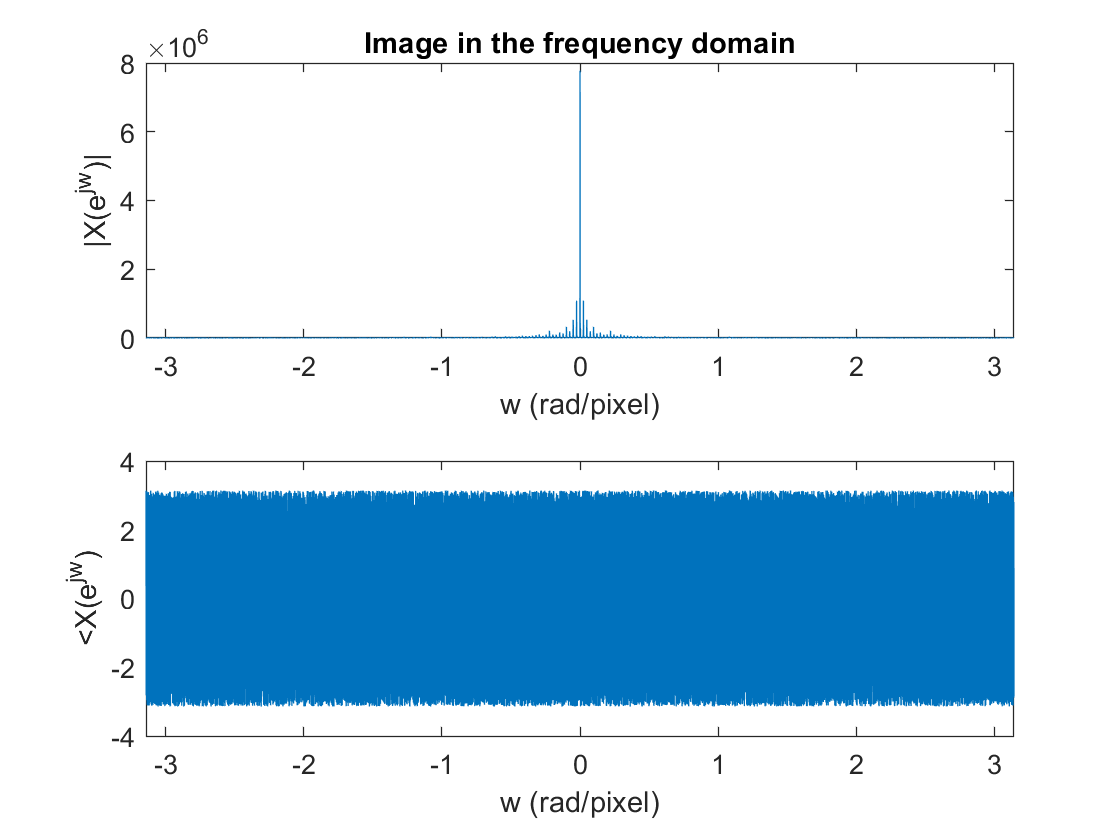

x = I(:);
X = fftshift(fft(x));
wValues= linspace(-pi,pi,length(x)); %DTFT is unique only from -pi to pi!

close all;
subplot(2,1,1);
plot(wValues,abs(X));
xlabel('w (rad/pixel)');
ylabel('|X(e^{jw})|');
xlim([-pi pi]);
title('Image in the frequency domain');
subplot(2,1,2);
plot(wValues,angle(X));
xlim([-pi pi]);
xlabel('w (rad/pixel)');
ylabel('<X(e^{jw})');

Similar to the case of a continuous-time audio signal, most of the frequency content is at low frequencies, and the phase is a bit difficult to interpret. Let's try looking at the signals with the magnitude or phase removed to see what they do.

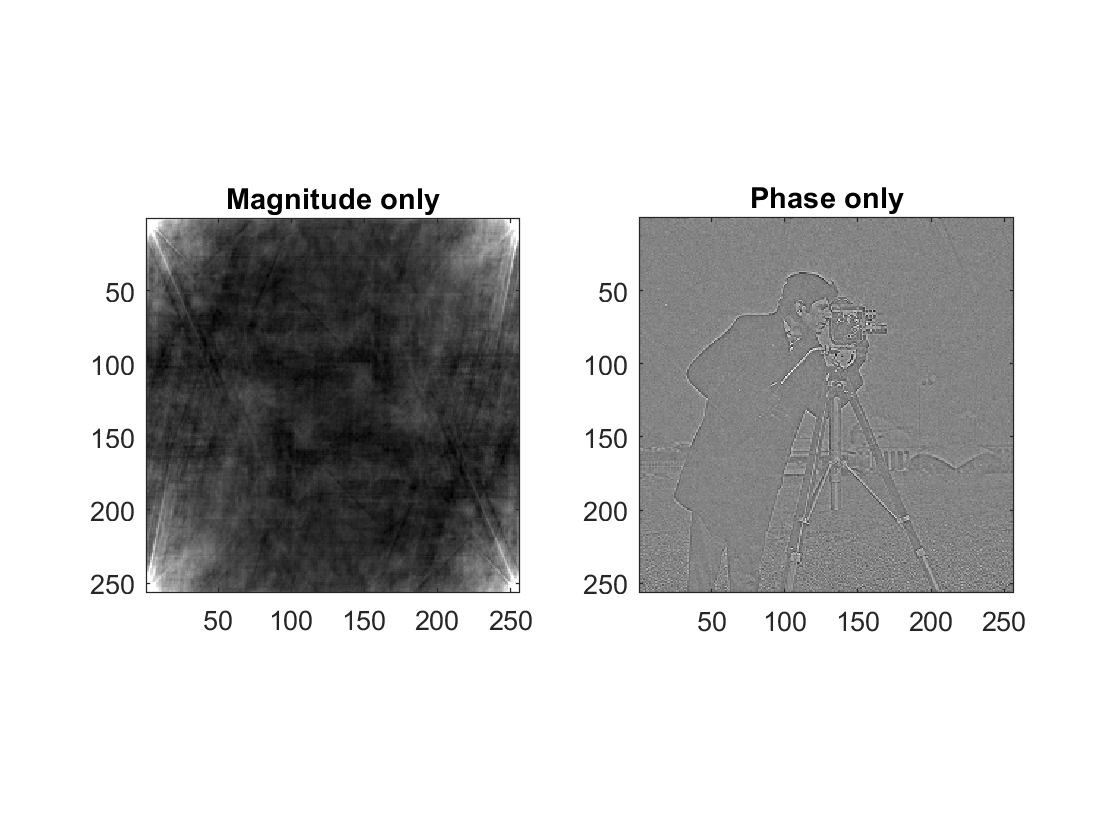

Xmag = abs(X);
xMag = min(ifft(ifftshift(Xmag)),400); %Artifically clip the pixel intensities for better display
IMag = reshape(xMag,HEIGHT,LENGTH);

Xphase = X./Xmag;
xPhase = ifft(ifftshift(Xphase));
IPhase = reshape(xPhase,HEIGHT,LENGTH);

close all;
subplot(1,2,1);
imagesc(IMag./sum(xMag));
pbaspect([1 1 1]);
title('Magnitude only');

subplot(1,2,2);
imagesc(IPhase);
pbaspect([1 1 1]);
title('Phase only');
colormap gray;

Similar to the audio signal, the magnitude alone gives us the "content" of the image, but all jumbled up. On the other hand, the phase tells us how to arrange all of the content, but the specific color information is missing.

A final fun fact is that we can take a 2D Fourier transform for working with images. Essentially we take the transform in the x and y directions jointly, and the result is a magnitude and phase plot that we can visualize as images.

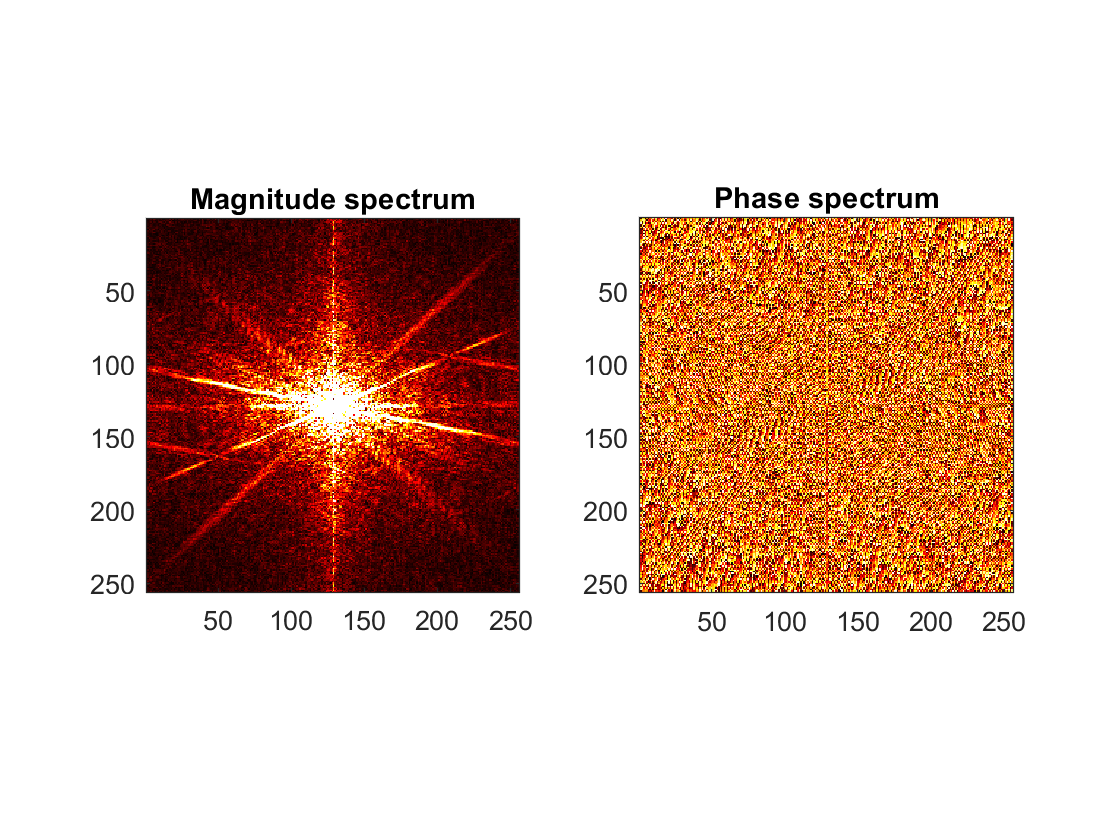

X2d = fft2(I); %transform of the 2D image

close all;
subplot(1,2,1);
imagesc(min(fftshift(abs(X2d)),20000)); %Clip the values for better display
pbaspect([1 1 1]);
title('Magnitude spectrum');

subplot(1,2,2);
imagesc(fftshift(angle(X2d)));
pbaspect([1 1 1]);
title('Phase spectrum');
colormap hot;

This tells us frequency information in two dimension: the x axis tells us how fast the frequency component oscillates in the x direction, and the y axis tells us how fast it oscillates in the y direction. The diagonal spikes correspond to freqeuency components that vary quickly in x and y simultaneously. Again we can see that this signal is mostly low-pass. Next lecture we'll spend some time understanding what these frequency components look like when we look at digital filters.